% House Keeping
clear;
clc;

#### Errikos Flight Regime Sample

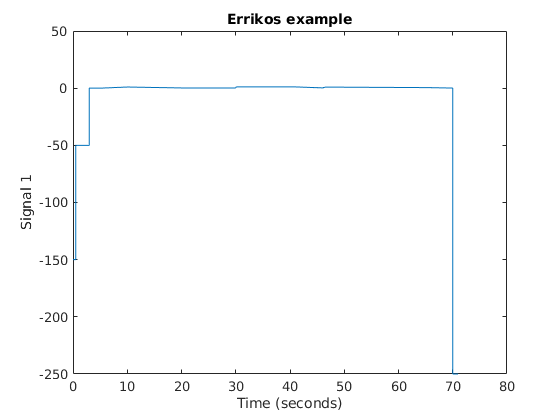

errikos_test = load("./Simulink Testing/samplemission.mat");
errikos_test = errikos_test.Scenario{1};

plot(errikos_test);
title("Errikos example");

#### Variables for Generating Flight Regimes

flightLen_max = 300;  % 5 mins
flightLen_min = 60;   % 1 min

sampleT = 0.05; % from the Testing_Model simulink
samplingFreq = 1/0.05; 

#### Generating Flight Regimes

flightReg_finalT = randi([flightLen_min, flightLen_max], 1, 1000); % getting random flight durations


figure()
hold on
for i = 1:1

    fprintf("Duration of flight test: %d seconds", flightReg_finalT(i));
    
    % getting all the t_i for the given flight duration
    flightReg_time = [0:sampleT:flightReg_finalT(i)];
    flightReg_time = round(flightReg_time,2);
    
    % generating desired heights
    flightReg_DesiredHeight = zeros(1,length(flightReg_time));
    
    % OLD IDEA
    % num_sections = round(flightReg_finalT(i)/3); % divide "flight test" into sections of 3 seconds
    
    
    % This selects the number of sections we will divide the flight regime
    % into
    %num_sections = round(0.05 * flightReg_finalT(i) );
    num_sections = 3;
    
    % r (array) holds the duration of each section
    %r = rand(1, num_sections)*.1;          % generating r
    r = rand(1, 3)
    r = r / sum(r);                     % sum of r = 1
    r = r .* flightReg_finalT(i);       % sum of r = flight test time
   
    % Duration of each section is rounded to the closest 0.05 
    % (i.e. closest sampleT)
    for j = 1:length(r)
        r(j) = round(r(j)/sampleT)*sampleT;
    end
    
   
    
    % For each Section Generate a Signal
    starting_t  = 0.00;
    starting_idx = 1;
    last_x = 0;
    last_y = 0;
    for m = 1:length(r)
       
        section_duration = r(m); % just for readability
        
        
        fprintf("m = %d; starting time %.2f; section duration %.2f\n", m, starting_t, section_duration);
        
        
        % Variables that "selects" the signal type of each section
        temp = rand();
        
        if starting_t ~= 0
             last_x = flightReg_time(starting_idx -1);
             last_y = flightReg_DesiredHeight(starting_idx -1);
        end
        
        % Sin Case
        if (temp < 0)
            
            % Getting random coefficients and Sin Output
            [a,b,c,f] = new_sine_coef();
            section_output = discSin([0.0:sampleT:section_duration], a, b, c, f);
            
            fprintf("SINE: a=%.2f, b=%.2f, c=%.2f, f=%.2f", a, b, c, f);
            
            % Adding result to flightReg_DesiredHeight
            temp2=1;
            for (k = find(flightReg_time==starting_t):find(flightReg_time==starting_t + section_duration)-1)
                flightReg_DesiredHeight(k) = flightReg_DesiredHeight(k) + section_output(temp2);
                temp2 = temp2 + 1;
            end
        
            
        % Linear Case
        elseif (temp < 1)
            
            % Getting random coefficients and Linear Output
            [m, b] = new_line_coef(last_x, last_y);
            section_output = discLin([starting_t:sampleT:starting_t+section_duration], m, b);
            
            % Debugging
            %fprintf("Size output: %f", size(section_output));
            %fprintf("LINE: m=%.2f, b=%.2f", m, b);
            %fprintf("Starting idx: %f", starting_idx);
            %fprintf("FInal idx: %f", final_idx);
            
        % Exp Case
        else
            
            % Getting random coefficients and Exp Output
            [a,b,c] = new_exp_coef(last_x, last_y);
            section_output = discExp([starting_t:sampleT:starting_t+section_duration], a, b, c);
                        
            % Debugging
            %fprintf("EXP: a=%.2f, b=%.2f, c=%.2f", a, b, c);
            
            
        end
        
        final_idx = starting_idx + round(section_duration/sampleT);
        
        % Adding result to flightReg_DesiredHeight
        for (k = starting_idx:final_idx-2)
            flightReg_DesiredHeight(k) = flightReg_DesiredHeight(k) + section_output(k-starting_idx + 1);
        end
        flightReg_DesiredHeight(final_idx-1) = flightReg_DesiredHeight(final_idx-1) + section_output(final_idx-starting_idx);
        
        
        starting_t = starting_t + section_duration;
        starting_idx = final_idx;
    end
    
    
    % probably unnecessary check!! just making sure the rounding above does
    % not break anything
    a = sprintf("%0.2f",sum(r));
    if (a == [int2str(flightReg_finalT(i)) + ".00"])
        disp("all good!");
    end
    
    
    % There is smth not right!!; this should be already done in each
    % subsection
    %flightReg_DesiredHeight = capArray(flightReg_DesiredHeight);
    
    
    % Plotting Generated Flight Regime
    plot(flightReg_time, flightReg_DesiredHeight);

end

Duration of flight test: 226 seconds

r =     0.1891    0.9299    0.4905


m = 1; starting time 0.00; section duration 26.55
m = 2; starting time 26.55; section duration 130.55
m = 3; starting time 157.10; section duration 68.90


all good!


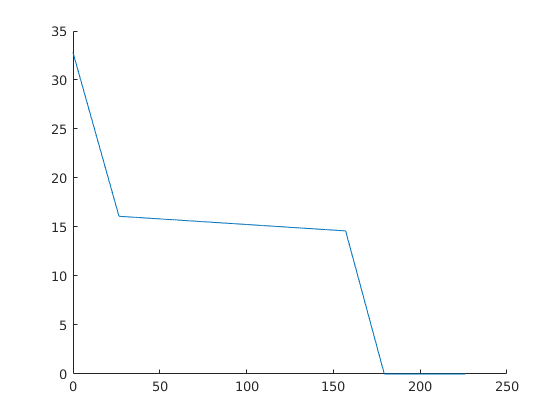

hold off

%num_sections = randi([5, 20]); % number of different "flight stages" during the test 
%flightReg_time
%time_array = [12:0.05:22]
flightReg_DesiredHeight;

%{
OLD METHODOLOGIES IN LINEAR CASE

            % Adding result to flightReg_DesiredHeight
            %temp2=1;
            %for (k = find(flightReg_time==starting_t):find( abs(flightReg_time - end_t)<1e-3 )-1)
            %    %disp(k)
            %    flightReg_DesiredHeight(k) = flightReg_DesiredHeight(k) + section_output(temp2);
            %    temp2 = temp2 + 1;
            %end
%}

#### # Debugging purposes only!

note that the comments are just what i though was reasonable values for the flight regime

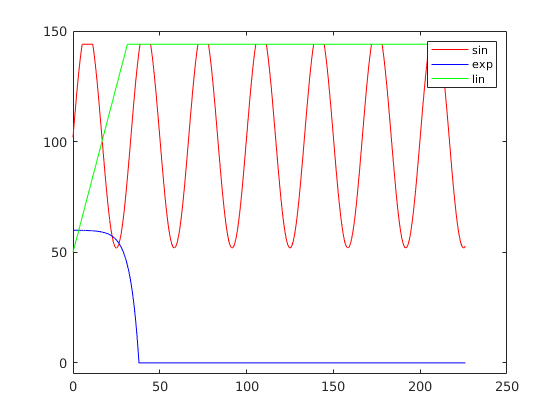

figure()

a = 50;     % amplitude between         [5, 40] cm
b = 102;    % oscillation mean between  [0, 144] cm
c = 0;      % phase shift between       [0, 2*pi] rad
f = 0.03;   % frequency between         [0.03, 0.15] 
output = discSin(flightReg_time, a, b, c, f);
plot(flightReg_time, output, "r")

hold on

%MIGHT NEED TO FIX THE RANGE OF A AND C FOR THE EXPONENT, NOT SURE IM CURRENTLY GETTING THE FULL RANGE (i.e. e^-x)%

a = -.03;     % ----                     [-0.5, 0.5]
b = 60;     % y intercept between       [0, 144] cm
c = 0.2;    % ----                      [0.2, 0.5]
output = discExp(flightReg_time, a, b, c);
plot(flightReg_time, output, "b")

m = 3;     % slope between             [-70, 70] (note that large slopes simulate step changes)
b = 50;     % y intercept between       [0, 144] cm
output = discLin(flightReg_time, m, b);
plot(flightReg_time, output, "g")

% introduce step change!! function (i.e. linear with different ranges of m)
% [-70, 70] (note that large m slopes simulate step changes)

legend("sin", "exp", "lin")
ylim([-5,150]);  % to check that the capping is working
hold off

### Signal Generation Functions

#### Capping possible values

function [capped_array] = capArray(capped_array)
    capped_array(capped_array>144) = 144;
    capped_array(capped_array<0) = 0;
end

#### Sine: $y = A\cdot \sin(2\pi \cdot f\cdot t+c) + b$

function [output_array] = discSin(time_array, a, b, c, f)
    output_array = a .* sin(2 .* pi .* time_array .* f + c) + b;
    output_array = capArray(output_array);
end

#### Exp: $y = A\cdot \exp(c \cdot t) + b$

function [output_array] = discExp(time_array, a, b, c)
    output_array = a .* exp(c .* time_array) + b;
    output_array = capArray(output_array);
end

#### Exp: $y = m\cdot x+b
$

function [output_array] = discLin(time_array, m, b)
    output_array = (time_array .* m) + b;
    output_array = capArray(output_array);
end

#### Coefficient Generator Functions

function [a,b,c,f] = new_sine_coef()
    % Generating random sine coefficients
    a = 35 * rand() + 5;
    b = 144 * rand();
    c = 2*pi * rand();
    f = 0.12 * rand() + 0.03;
end

function [m, b] = new_line_coef(last_x, last_y)
    % Generating random linear coefficients
    m = 2 * rand() - 1;
    
    if last_x ~= 0
        % For continuity (prob need some constraint)
        b = last_y - (last_x * m);
    else
        b = 144 * rand();
    end
    
end

function [a, b, c] = new_exp_coef(last_x, last_y)
    % Generating random exponential coefficients
    a = rand() - 0.5;
    c = 0.3 * rand() + 0.2;
    
    if last_x ~= 0
        b = last_y - a * exp(c*last_x);
    else
        b = 144 * rand();
    end
end

### Performance Functions

function [track_error] = getPerformance(desiredH_arr, realH_arr)
    track_error = mean( (desiredH_arr - realH_arr).^2 ); % Mean square-error
end